%Justing closing all figures in windows
close all 


%First some data is simulated which is used to HAVOKc. 
clear
SampleNumber=1000;


%Setting up the A, B and C, matrix
% A=[0.8, 0.2, 0.5; 0.1, 0.9, 0.3; 0.2, 0.3,0.7]
% B=[0.3, 0.1;0.4,0.2;0.2,0.5]
% C=[0.6, 0.2, 0.4; 0.3, 0.5, 0.1]
A=[0.8, 0.2; 0.1, 0.9] 

A =     0.8000    0.2000
    0.1000    0.9000


B=[0.3, 0.1;0.4, 0.2]

B =     0.3000    0.1000
    0.4000    0.2000


C=[0.6, 0.2; 0.3, 0.5]

C =     0.6000    0.2000
    0.3000    0.5000



%Setting up inital condition:
x=[0;0];


index=2; %Index to save some numbers 
%Making simulation, to obtain data to base model
for i=0:SampleNumber-1
    %Determine input
  
    %In general, you can generate N
    %random numbers in the interval (a,b) 
    % with the formula r = a + (b-a).*rand(N,1).
    a=-1;
    b=1;

    u(1,index-1)=a+(b-a)*rand();
    u(2,index-1)=a+(b-a)*rand();

    x(:,index)=A*x(:,index-1)+B*u(:,index-1);
    y(:,index-1)=C*x(:,index);
    index=index+1;    
end
%**** the way u was make, so it needs to be transposed! 


%Getting the HAVOKc model of it
%nd=2 low model nd=6 good modle
nd=50;  %was 6 the embedded length (the amount for rows=nd*# outputs

%r=1 low model r=2 better model
r=10; %was 2  How much the SVD is truncated! 

%Getting the model in the V space, and the projection matrix up and down 
%Togehter with all singular values, which can be used to changes truncation
%value
[Av, Bv, Pup, Pdown,S,Sr] =HAVOKc_model(y,u,nd,r);
cond(Sr)

ans = 45.3728

testModel=1; %1=making one step prediction 
%on the data which the model was trained for 
%0=not doing it 
n=size(C,1)

n = 2

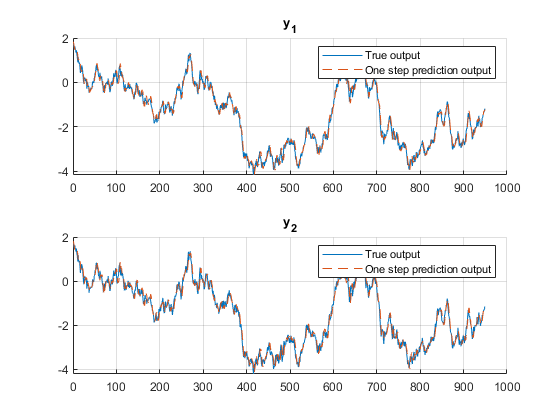

Cc=[];
for i=1:n
Cc=[Cc; zeros(1,i-1),1,zeros(1,nd*n-i+n)]; %No idea if Cc is correct 
end 
if testModel==1
%Testing the model on the same data it was made on: 
indexY=1;
    for i=nd:size(y,2)-1
         clear Hr;
         index=1;
        for j=i+1:-1:i-nd+1
            Hr(index:index+n-1,:)=y(:,j);
            index=index+n;
        end
    
         clear Hru 
         index=1;
        for j=i+1:-1:i-nd+1
            Hru(index:index+n-1,:)=u(:,j);
            index=index+n;
        end
        
        vT=Pdown*Hr;
        
        uv=Pdown*Hru; 
        
        xMPC=Av*vT+Bv*uv;
        
        dummy=Pup*xMPC; 

        yPre(:,indexY)=Cc*dummy;
        indexY=indexY+1;
    end
    clf
    subplot(2,1,1);
    hold on 
    plot(y(1,nd+n:end))
    plot(yPre(1,:),'--')
    hold off
    legend('True output','One step prediction output')
    set(gcf,'Visible','on')
    title('y_1')
    grid

    subplot(2,1,2);
    hold on 
    plot(y(2,nd+n:end))
    plot(yPre(2,:),'--')
    hold off
    legend('True output','One step prediction output')
    title('y_2')
    grid
    
    set(gcf,'Visible','on')

end 

%Now there is looked at setting op the setting up the optimziatoin problem 
%First the problem is defined
Problem=optimproblem();

%Afterward the optimizitation variable Delta U is defined. This is achied
%as the number of inputs nu multiplied with the control horizion Hc
nu=size(B,2); % Number of inputs

Hc=20; %Control horizion 
%The control horizion is first limited, as a optimization parameter after
%the control horizion, but as many optimization variable is included
Hp=30; %Prediction horizion


dU=optimvar('dU',Hp*nu,1); %Limits in the constructation of the optimization problem and not here! 

%Likewise the optimization variable eta is defined. 
% The size of eta corresponds to 2*r, thereby it beocmes: 
ny=size(C,1); %Number of outputs
eta=optimvar('eta',Hp*(r+ny)+(r+ny),1); 
%Next the cost function J, defined in the report, is defined. 
%But First it is neccesary to obtain the lifted weights Q and R 
%All deltaV is multipled with 100, the number of v's=r
Q=[ones(1,r)*5000,1000,1];
%Q=[ones(1,r)*5000,1,1000];

R=[1,1]; 

QR=lifting_QR(Q,R,Hp); 

J=0.5*[eta', dU']*QR*[eta; dU]; 

%J=[eta', dU']*QR*[eta; dU];
Problem.Objective=J;



%Afterwards there is looked at the constrant constraints, in this case 
%The input slew rate. (input range changes due to the past input changing) 
W=[-1, 0; 1,0; 0,-1;0,1]

W =     -1     0
     1     0
     0    -1
     0     1



w=[-0.1;-0.1;-0.2;-0.2]; 

[WLift,wLift] =lifting_slew_rate_constraints(Hp,W,w);

%[WLift,wLift] =lifting_slew_rate_constraints(Hc,W,w);

Problem.Constraints.Slew_rate= le(WLift*dU+wLift,zeros(size(WLift,1),1));

%Starting to set up the part which will have to changes at each iteration 
ControlRunTime=250; %How long the MPC should run for


%Refarence signal for setting inital value of Eta, here the the desired
%refarence signal is needed

%Not complety sure this is the correct way to make refarence
Ref=[ones(1,100)*5,ones(1,150+2)*2;ones(1,100)*2,ones(1,150+2)*1];

%Making inital condition for the output measurement, in this case it been 0
DeltaZ0=zeros((nd+1)*ny,1);
DeltaZy=DeltaZ0; 

uMPC=zeros(2,1); 

%States for the "real-world" model  
xMPC=zeros(2,1); 

%Prepring for input range constraints: 

Fis=[-1,0; 1,0;0,-1;0,1];  %Matrix this uk is mutilpied on
f=[-1;-1;-1;-1];  %constant matrix
[F, f1, f,Fi]=lifting_input_constraints(Hp,Fis,f);

%To show refarence changes in the prediction horizion, therefore it is neccesary to only 
%Have a value different from 0 at the time the refarence is changes! 
RefV2=zeros(2,ControlRunTime*(ny)+Hp*(ny));  
%RefV2(1,1)=-5; %start refarence at 5 
%RefV2(2,1)=-2; %start refarence at 5 
RefV2(1,100)=3; %change in refarence  5-2=3 
RefV2(2,100)=1; %change in refarence  5-2=3 

%Define the inital value of eta_0 for the first time: 
  %Starting by determine the inital value of Eta
    %Determing DeltaV^T: 
    DeltaVtranspose=Pdown*DeltaZy; 

    %Determine Eta0
    eta_0=[DeltaVtranspose;-Ref(:,1)]; 



%Making the for loop part the makes it run
for i=1:ControlRunTime
    %Setting up the input constraints (dependes on the last input) 
    Problem.Constraints.input= F*dU<=-f1*uMPC(:,i)-f; 

    %Making lifting for the dynamics 
    [F_eta, Fu, F0, b,F_r(:,i),RowAn] =lifting_dynamics(Av,Bv,Pup,Pdown,nd,r, Hp,Hc,nu,DeltaZ0,eta_0,RefV2,ny);


    %Setting up the dynamics constraints no refarence changes include
    %Problem.Constraints.dynamics=[F_eta,Fu]*[eta;dU]==(b-F0);
    
    %Setting up the dynamics constraints with refarence changes include
    
    %Problem.Constraints.dynamics=[F_eta,Fu]*[eta;dU]+F_r(:,i)==(b-F0);
    Problem.Constraints.dynamics=[F_eta,Fu]*[eta;dU]==(b-F0)
    
    
    %Setting up constraints so that the change in input is constant 0 after
    %the prediction horizion
    Problem.Constraints.input_control_horizion=dU(Hc*(nu)+nu:end,:)==0; 
    
    %That should all the constraints setup now it is possible to solve the
    %optimization problem 
    solution=solve(Problem); 
    
    solutionAllu(:,:,i)=solution.dU;


    solutionAlleta(:,:,i)=solution.eta;

    %Determine the input value:
    uMPC(:,i+1)=uMPC(:,i)+solution.dU(1:2,1); 
    
    %Updating the change in input for the inital input sequence
   
    %DeltaZ0=[DeltaZ0(2:end,1);solution.dU(1,1)];

    DeltaZ0=[solution.dU(1:2,1);DeltaZ0(1:end-2,1)];



    %Determine DeltaVtransponse, as the prediction, as it would be the same! 
    %Takes out the first DeltaVtranspose, as predited, as it would be the
    %same as prediction down determine it and prediction backup, 
    
    DeltaVtranspose=solution.eta(r+ny+1:2*r+ny,:); 

    %DeltaVtranspose=solution.eta(r+ny+1:2*r+1,:); 



    % Determine the output from the system 
    xMPC(:,i+1)=A*xMPC(:,i)+B*uMPC(:,i+1);
    yMPC(:,i+1)=C*xMPC(:,i+1);
    RefV2=RefV2(:,2:end); 
    %eta_0=[DeltaVtranspose;yMPC(:,i)-Ref(:,i)]; 
    eta_0=[DeltaVtranspose;yMPC(:,i)-Ref(:,i)]; 
    
   
end 

Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 3 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Problem =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 2 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


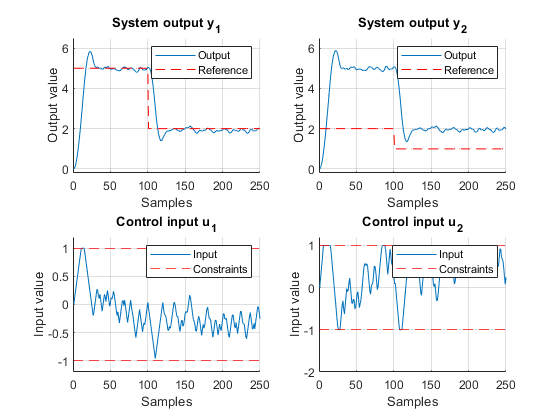



%Ploting the system output
%figure(1)
%figure('Name','System output','NumberTitle','off');
clf
subplot(2,2,1);
hold on
plot(yMPC(1,:))
plot(Ref(1,:),'--r')
hold off 
grid
xlim([0 250])
ylim([-0.2 6.5])
legend('Output','Reference')
title('System output y_1')
xlabel('Samples')
ylabel('Output value')

subplot(2,2,2);
hold on
plot(yMPC(2,:))
plot(Ref(2,:),'--r')
hold off 
grid
xlim([0 250])
ylim([-0.2 6.5])
legend('Output','Reference')
title('System output y_2')
xlabel('Samples')
ylabel('Output value')



%Plotting the input to the system 
%figure(2)
%figure('Name','Control input','NumberTitle','off');
subplot(2,2,3);
hold on 
plot(uMPC(1,:))
yline(1,'--r')
yline(-1,'--r')
hold off 
legend('Input','Constraints')
grid 
xlim([0 250])
ylim([-1.2 1.2])
title('Control input u_1')
xlabel('Samples')
ylabel('Input value')


subplot(2,2,4);
hold on 
plot(uMPC(2,:))
yline(-1,'--r')
yline(1,'--r')
hold off 
legend('Input','Constraints')
grid 
xlim([0 250])
ylim([-2 1.2])
title('Control input u_2')
xlabel('Samples')
ylabel('Input value')






ax=gca;
%exportgraphics(gcf,"Two_in_out_MPC_test_result_2.pdf",'ContentType','vector')


set(gcf,'Visible','on')


